# Examples for using the planet3D and background functions.

Copyright © 2021 Tamas Kis

### Plot a celestial body with the Milky Way in the background.

Initialize the figure and plot the background.

figure;
background('Milky Way');

Plot the celestial body (comment/uncomment to choose which one to plot -- for this example, we plot the Earth with clouds).

%planet3D('Sun');
%planet3D('Moon');
%planet3D('Mercury');
%planet3D('Venus');
%planet3D('Earth');
planet3D('Earth Cloudy');
%planet3D('Earth Night');
%planet3D('Earth Night Cloudy');
%planet3D('Mars');
%planet3D('Jupiter');
%planet3D('Saturn');
%planet3D('Uranus');
%planet3D('Neptune')
%planet3D('Pluto');

Set a light source at a specific position.

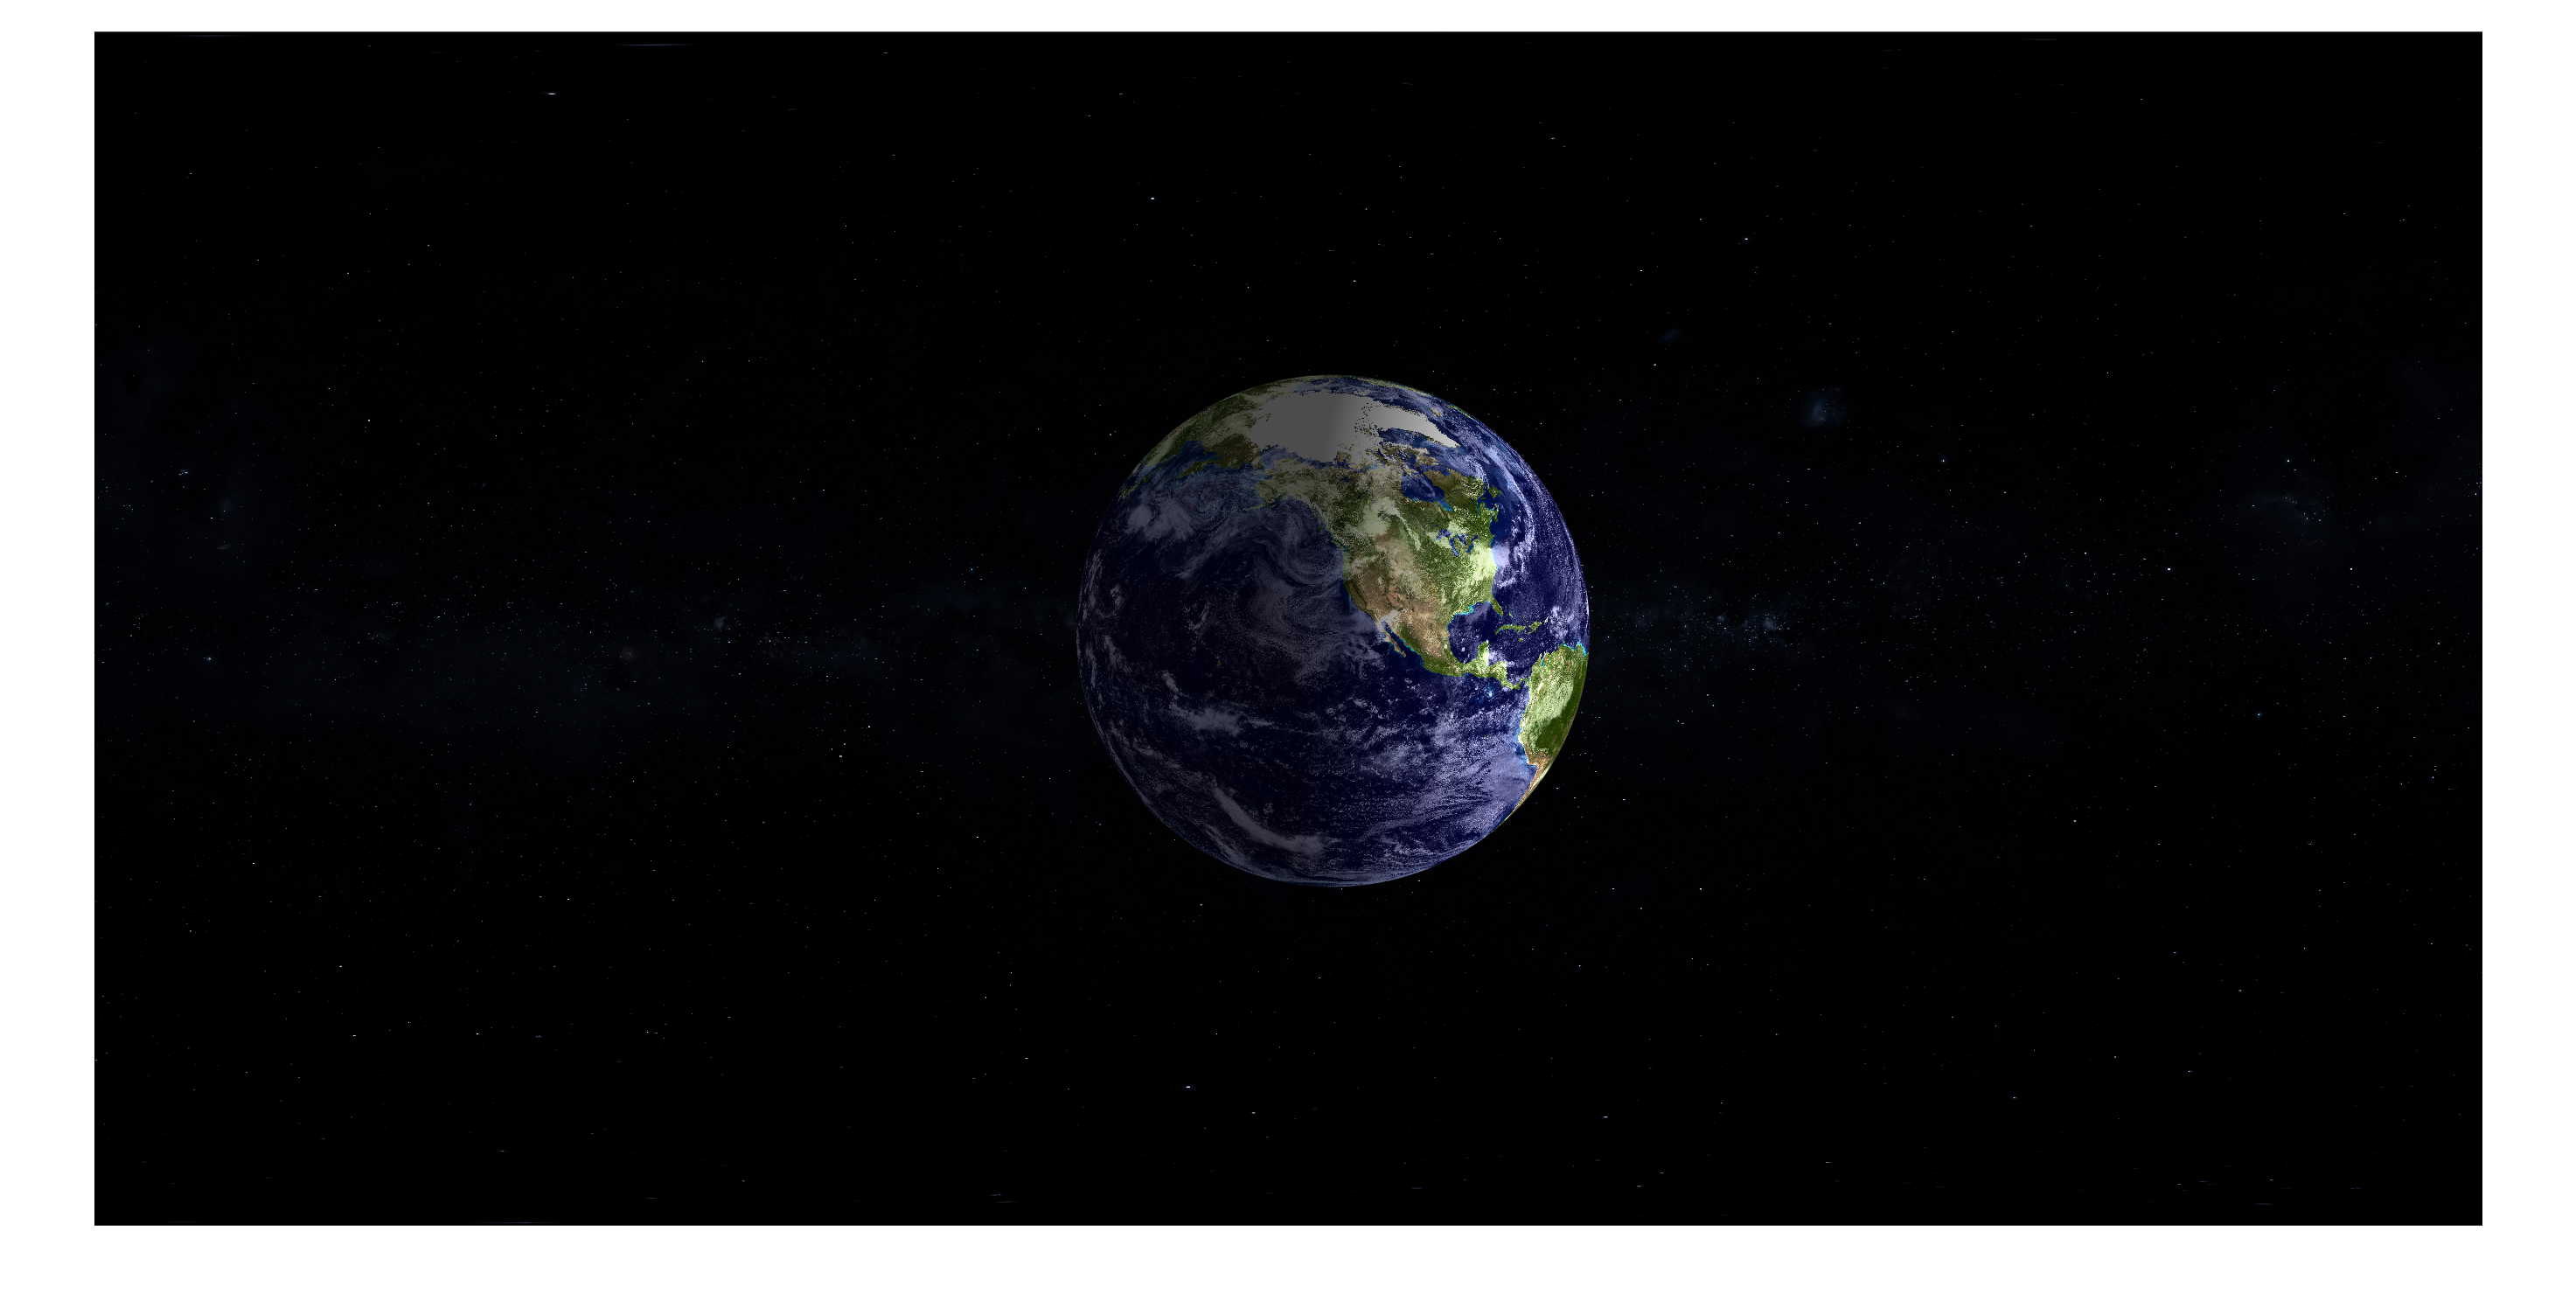

light('Position',[1,-1,0]);

### Plot Saturn with respect to the ecliptic plane on white background with grid lines.

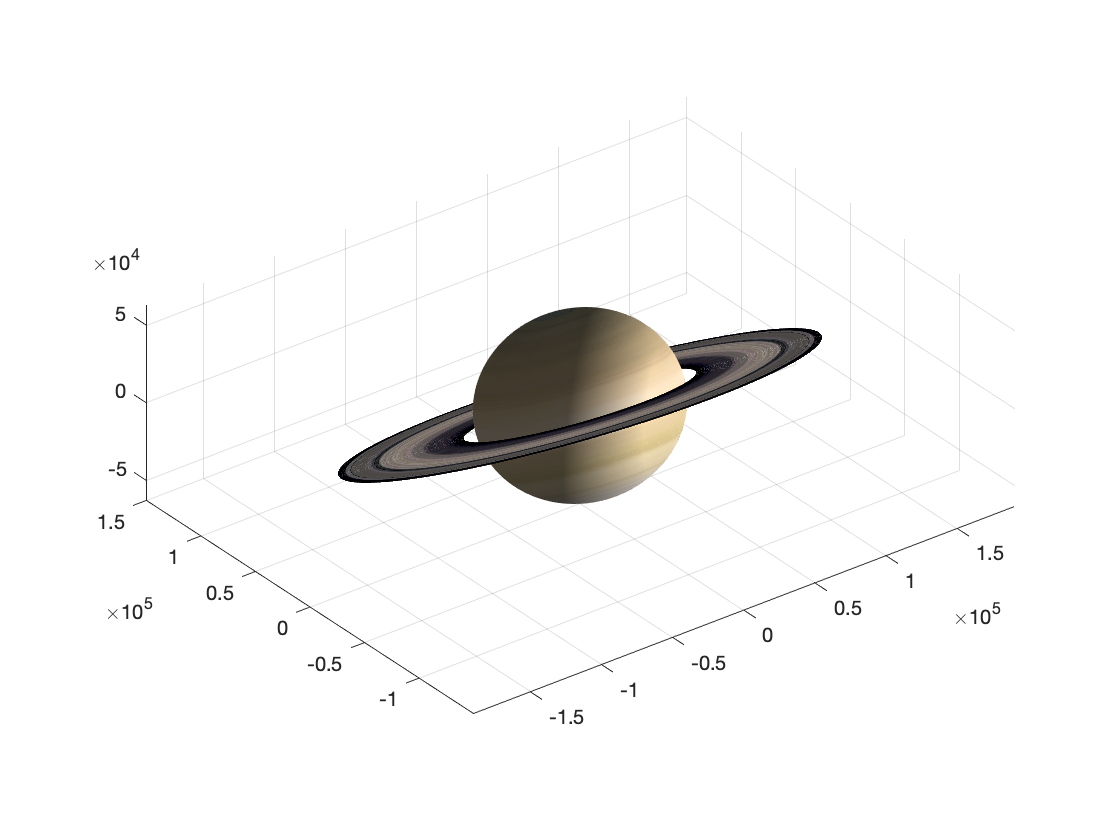

figure;
planet3D('Saturn',[],[],'ecliptic')
light('Position',[1,-1,0]);
grid on;

### Plot elliptical trajectory around Earth on black background with grid lines.

We first need to set orbit parameters.

p = 15000;  % semi-latus rectum [km]
e = 0.5;    % eccentricity
i = 45;     % inclination [deg]
Om = 245;   % right ascension of the ascending node [deg]
w = 0;      % argument of periapsis [deg]

Next, we can determine  the orbit in the perifocal plane.

% array for true anomaly [rad]
nu = 0:0.01:(2*pi);

% position components in perifocal frame [km]
rP = p*cos(nu)./(1+e*cos(nu));
rQ = p*sin(nu)./(1+e*cos(nu));
rW = zeros(size(nu));

We then rotate the position components from the perifocal frame to the Earth-centered inertial (ECI) frame.

% precomputes trigonometric functions
sO = sind(Om);
cO = cosd(Om);
si = sind(i);
ci = cosd(i);
sw = sind(w);
cw = cosd(w);

% rotation matrix
R_pqw2eci = [cO*cw-sO*ci*sw   -cO*sw-sO*ci*cw    sO*si;
             sO*cw+cO*ci*sw   -sO*sw+cO*ci*cw   -cO*si;
             si*sw             si*cw             ci];

% rotates coordinates of orbit to ECI frame
r_eci = R_pqw2eci*[rP;rQ;rW];
rI = r_eci(1,:);
rJ = r_eci(2,:);
rK = r_eci(3,:);

We intialize the figure, plot a plain black background, plot the Earth (with clouds) with 75% transparency, plot the orbit, and label the axes.

% initialize figure
figure;

% set background
background('Black');

% plot Earth with 75% transparency (25% opacity) and the orbit
hold on;
planet3D('Earth Cloudy',[],[],[],[],0.25);
plot3(rI,rJ,rK,'color',[140,21,21]/255,'linewidth',1.5);
hold off;

% label axes
xlabel("$I\;[\mathrm{km}]$",'interpreter','latex','fontsize',18);
ylabel("$J\;[\mathrm{km}]$",'interpreter','latex','fontsize',18);
zlabel("$K\;[\mathrm{km}]$",'interpreter','latex','fontsize',18);

To plot a grid on the black background, we set the grid lines to white and change their transparency to 75% transparency (i.e. 25% opacity).

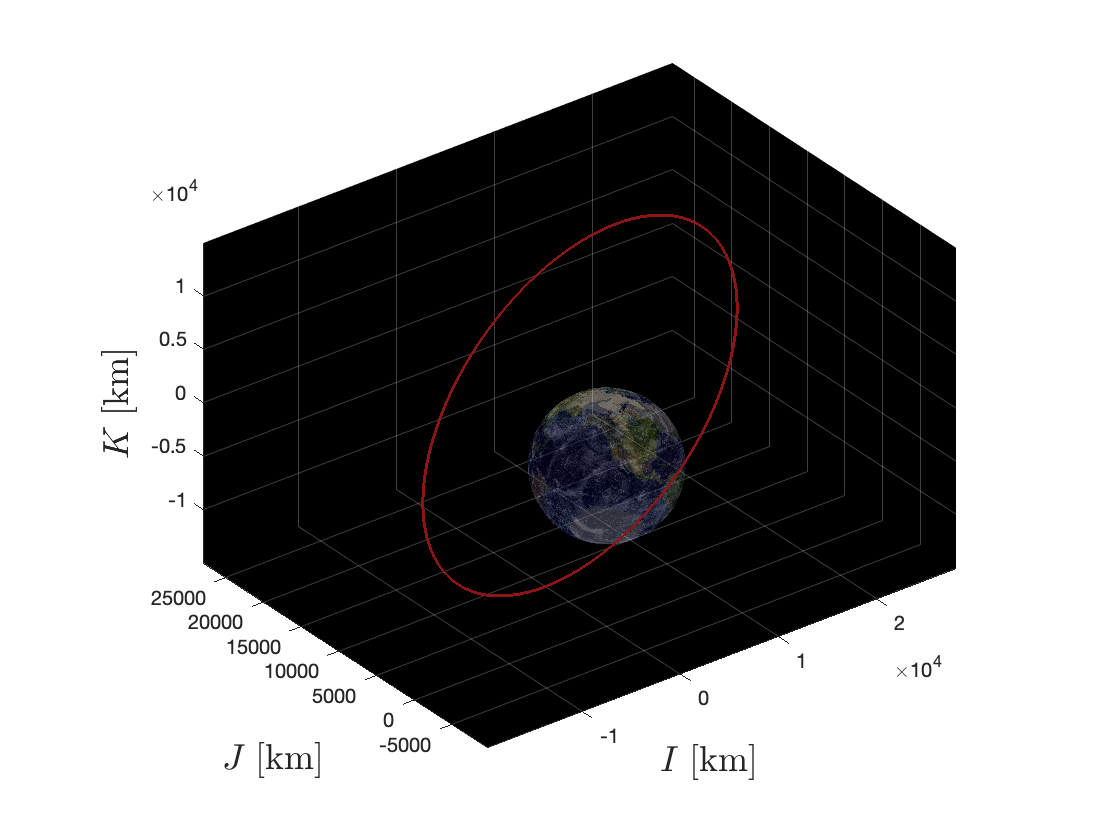

% turn grid on
grid on;

% get axis handle
ax = gca;

% set grid lines to white
ax.GridColor = [1,1,1];

% set grid lines to 75% transparency (25% opacity)
ax.GridAlpha = 0.25;